format long eng;
kbr1b_x = importdata("KBR1B_2020-09-28_Y_04.txt");
gni1b_a = importdata("GNI1B_2020-09-28_C_04.txt");
gni1b_b = importdata("GNI1B_2020-09-28_D_04.txt");
sca1b_a = importdata("SCA1B_2020-09-28_C_04.txt");
sca1b_b = importdata("SCA1B_2020-09-28_D_04.txt");

los = gni1b_b.data(:, 1: 3) - gni1b_a.data(:, 1: 3);
dis = sqrt(sum(los.^2, 2));
los = los ./ dis;
rotm_a = zeros(17280, 3, 3);
rotm_b = zeros(17280, 3, 3);
eqa = zeros(17280, 6);
eqb = kbr1b_x(:, 2) - dis(1: 5: end);
for i = 1: 17280
    eqa(i, 1: 3) = los(i*5-4, :) * quat2rotm(sca1b_a.data(i*5-4, 2: 5));
    eqa(i, 4: 6) = los(i*5-4, :) * quat2rotm(sca1b_b.data(i*5-4, 2: 5));
end
diff_eqa = diff(eqa, 1);

diff2_eqa = diff(diff_eqa, 1);
diff3_eqa = diff(diff2_eqa, 1);
diff_eqb = diff(kbr1b_x(:, 2) - dis(1: 5: end));
diff2_eqb = diff(kbr1b_x(:, 2) - dis(1: 5: end), 2);
diff3_eqb = diff(diff2_eqb);
diff2_eqb = filter_pdfree(Num, diff2_eqb);
diff2_eqa = filter_pdfree(Num, diff2_eqa);
diff3_eqa = filter_pdfree(Num, diff3_eqa);
diff3_eqb = filter_pdfree(Num, diff3_eqb);
fft_diff3_eqb = fft(diff3_eqb(10522: 11021));
fft_diff3_eqa = [fft(diff3_eqa(10522: 11021, 4)), fft(diff3_eqa(10522: 11021, 5))];
eqb = [fft_diff3_eqb(11); fft_diff3_eqb(21)];
eqa = [fft_diff3_eqa(11, :); fft_diff3_eqa(21, :)];
eqa_real = real(eqa);
eqa_imag = imag(eqa);
eqb_real = real(eqb);
eqb_imag = imag(eqb);

eqa_abs = abs(eqa);
eqa_ang = angle(eqa);
eqb_abs = abs(eqb);
eqb_ang = angle(eqb);

lsqr(eqa, eqb)

lsqr 在解的 迭代 2 处收敛，并且相对残差为 1.1e-13。


lsqr([eqa_real(2, :); eqa_imag(2, :)], [eqb_real(2, :); eqb_imag(2, :)])

lsqr 在解的 迭代 2 处收敛，并且相对残差为 4.1e-15。


ans =     1.47490186363381e+000
    75.6945672643815e-003


lsqr(diff3_eqa(10522: 11122, :), diff3_eqb(10522: 11122))

lsqr 在解的 迭代 6 处收敛，并且相对残差为 0.047。


ans =    -2.40352009565077e-006
    13.2931030006575e-003
   -46.2212269809617e-003
    1.47498528573397e+000
    660.305493875648e-006
    54.7606208251241e-003


lsqr(diff2_eqa(10522: 11122, :), diff2_eqb(10522: 11122))

lsqr 在解的 迭代 6 处收敛，并且相对残差为 0.071。


ans =     33.0601299894499e-006
    27.3690577366649e-003
    27.6241752240636e-003
    1.47534503443176e+000
    748.407806693946e-006
    32.0464592321722e-003


lsqr(diff3_eqa(8256: 8856, :), diff3_eqb(8256: 8856))

lsqr 在解的 迭代 6 处收敛，并且相对残差为 0.033。


ans =    -18.7529819991597e-006
    17.6125260714211e-003
   -2.38169246761299e-003
    1.47831727894090e+000
   -192.115828120817e-006
   -37.9272759024271e-003


lsqr(diff2_eqa(8256: 8856, :), diff2_eqb(8256: 8856))

lsqr 在解的 迭代 6 处收敛，并且相对残差为 0.032。


ans =    -50.0661818991240e-006
    71.8793762444743e-003
   -47.6757991164151e-003
    1.47708298946770e+000
   -221.769144523874e-006
   -38.4295697637485e-003


solver_spectral(diff2_eqa(8256: 8856, :), diff2_eqb(8256: 8856), [4 5], 0.2)

lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.016。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.016。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.016。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.015。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.015。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.015。


ans =     389.956817107598e-009    11.0591024253597e-006
    191.866382394741e-009    56.4066046431208e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.036。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.036。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.036。


ans =     579.215827226220e-009
    283.281418677427e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 2.9e-09。


ans =     1.47635851958540e+000
    316.459349006745e-006


solver_spectral(diff3_eqa(8256: 8856, :), diff3_eqb(8256: 8856), [4 5], 0.2)

lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.041。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.041。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.041。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.049。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.049。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.049。


ans =     48.9491815825663e-009    1.38829087597180e-006
    48.1151945089724e-009    13.5713687472211e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.058。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.058。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.058。


ans =     72.6820491958239e-009
    71.0562625665562e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 1.2e-11。


ans =     1.47671377927236e+000
    286.768626609757e-006


solver_spectral(diff2_eqa(10522: 11122, :), diff2_eqb(10522: 11122), [4 5], 0.2)

lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.014。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.014。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.014。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.016。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.016。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.016。


ans =     382.348219153271e-009    11.0774808125687e-006
    194.560235455346e-009    52.6439223995293e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.07。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.07。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.07。


ans =     573.622335206452e-009
    287.578326618167e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 1.4e-09。


ans =     1.47788507143946e+000
    772.342497310889e-006


solver_spectral(diff3_eqa(10522: 11122, :), diff3_eqb(10522: 11122), [4 5], 0.2)

lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.034。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.034。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.034。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.05。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.05。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.05。


ans =     48.0180274556870e-009    1.39127470504664e-006
    48.7653030341805e-009    12.5754490606588e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.06。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.06。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.06。


ans =     71.9847856982631e-009
    72.1800580060736e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 1.4e-10。


ans =     1.47998160509123e+000
    660.536943304854e-006


solver_spectral(diff2_eqa(10522: 10921, :), diff2_eqb(10522: 10921), [4 5], 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.014。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.014。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.014。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.016。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.016。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.016。


ans =     382.191816936787e-009    11.0768832907510e-006
    194.295838200030e-009    50.7336066778661e-009


lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.063。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.063。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.063。


ans =     576.429915653174e-009
    287.830926552077e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 1.9e-09。


ans =     1.48116172409731e+000
    933.658299485905e-006


solver_spectral(diff2_eqa(10722: 11021, :), diff2_eqb(10722: 11021), [4 5], 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.012。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.012。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.012。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.014。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.014。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.014。


ans =     384.004618487754e-009    11.1133557236503e-006
    195.959435147269e-009    49.5621170321642e-009


lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.058。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.058。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.058。


ans =     577.458837689064e-009
    293.000221682158e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 1e-09。


ans =     1.49513296666975e+000
    298.818279512135e-006


solver_spectral(diff2_eqa(10622: 10921, :), diff2_eqb(10622: 10921), [4 5], 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.014。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.014。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.014。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.015。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.015。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.015。


ans =     382.480410189541e-009    11.0750630144916e-006
    194.200822195300e-009    36.7172131201495e-009


lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.062。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.062。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.062。


ans =     576.893868694582e-009
    288.993354541437e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 1.8e-10。


ans =     1.48798338457837e+000
    701.519576015192e-006


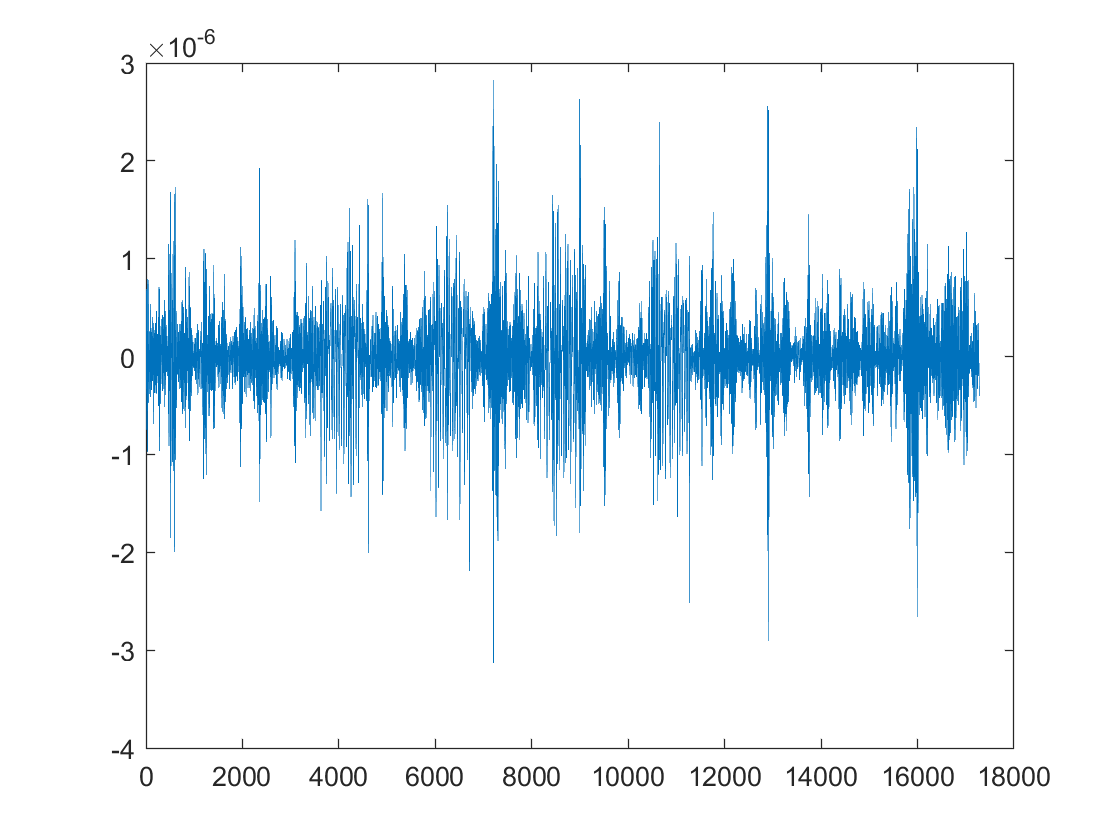

acc_grav = importdata("..//..//temp//acc_grav_calibra1.txt");
%vel_grac = cumtrapz(acc_grav, 1);
acc_grav_rela = [acc_grav(:, 1) - acc_grav(:, 4), acc_grav(:, 2) - acc_grav(:, 5), acc_grav(:, 3) - acc_grav(:, 6)];
%vel_grav_rela = [vel_grav(:, 1) - vel_grav(:, 4), vel_grav(:, 2) - vel_grav(:, 5), vel_grav(:, 3) - vel_grav(:, 6)];
gnv_a = importdata("GNV1B_2020-09-28_C_04.txt");
gnv_b = importdata("GNV1B_2020-09-28_D_04.txt");
gni_a = importdata("GNI1B_2020-09-28_C_04.txt");
gni_b = importdata("GNI1B_2020-09-28_D_04.txt");
kbr_x = importdata("KBR1B_2020-09-28_Y_04.txt");
range_acc = kbr_x(:, 4);

pos_rela = gnv_a.data(:, 1: 3) - gnv_b.data(:, 1: 3);
pos_rela_i = gni_a.data(:, 1: 3) - gni_b.data(:, 1: 3);
los = pos_rela ./ sqrt(sum(pos_rela.^2, 2));
los_i = pos_rela_i ./ sqrt(sum(pos_rela_i.^2, 2));
vel_rela = gni_a.data(:, 7: 9) - gni_b.data(:, 7: 9);
los_vec = vel_rela ./ sqrt(sum(pos_rela.^2, 2)) - pos_rela_i .* dot(los_i, vel_rela, 2) ./ sum(pos_rela.^2, 2);

range_acc_grav = zeros(length(los), 1);
for i = 1: length(range_acc_grav)
    range_acc_grav(i) = dot(acc_grav_rela(i, :), los(i, :)) + dot(vel_rela(i, :), los_vec(i, :));
end
range_acc_grav = range_acc_grav(1: 5: length(range_acc_grav));
range_acc_res = range_acc - range_acc_grav;
figure; plot(range_acc_res)

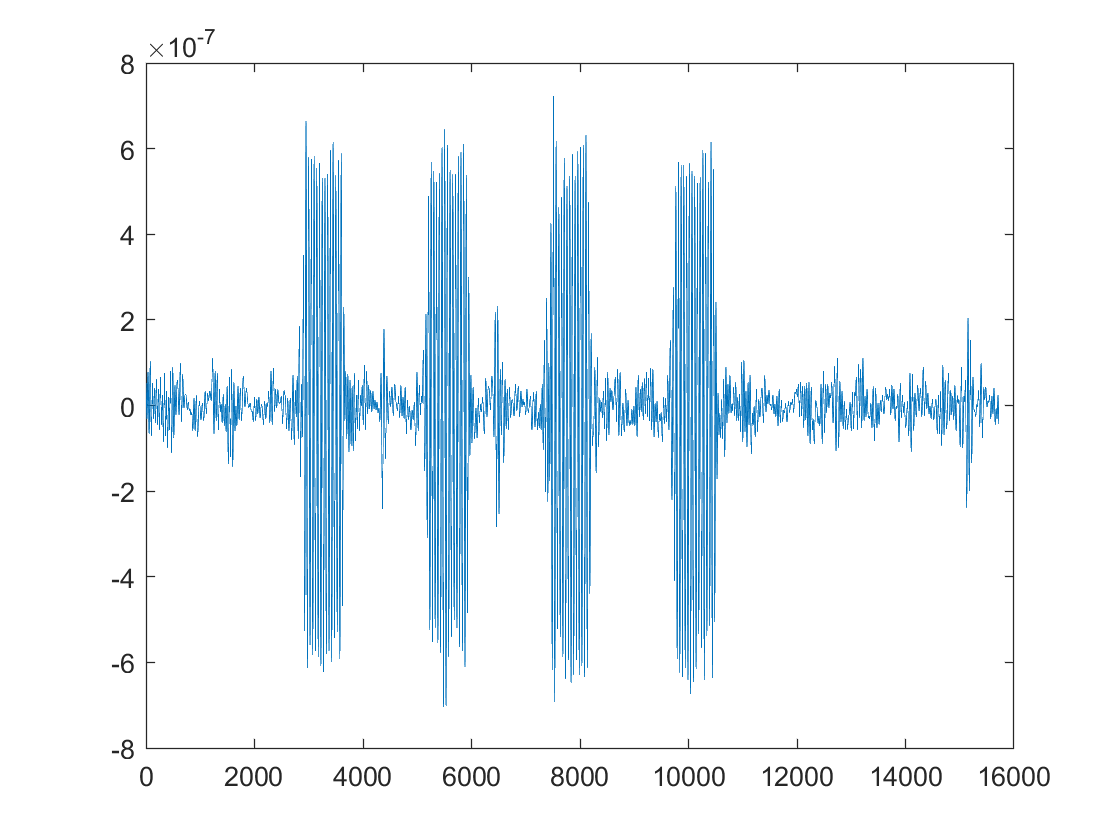

temp = filter_pdfree(Num1, range_acc_res);
figure; plot(temp)

spectral_component(temp(7488: 7488+600), 0.2)

lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.13。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.13。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.13。


ans =     589.545129726910e-009
    1.70395564090079e-009


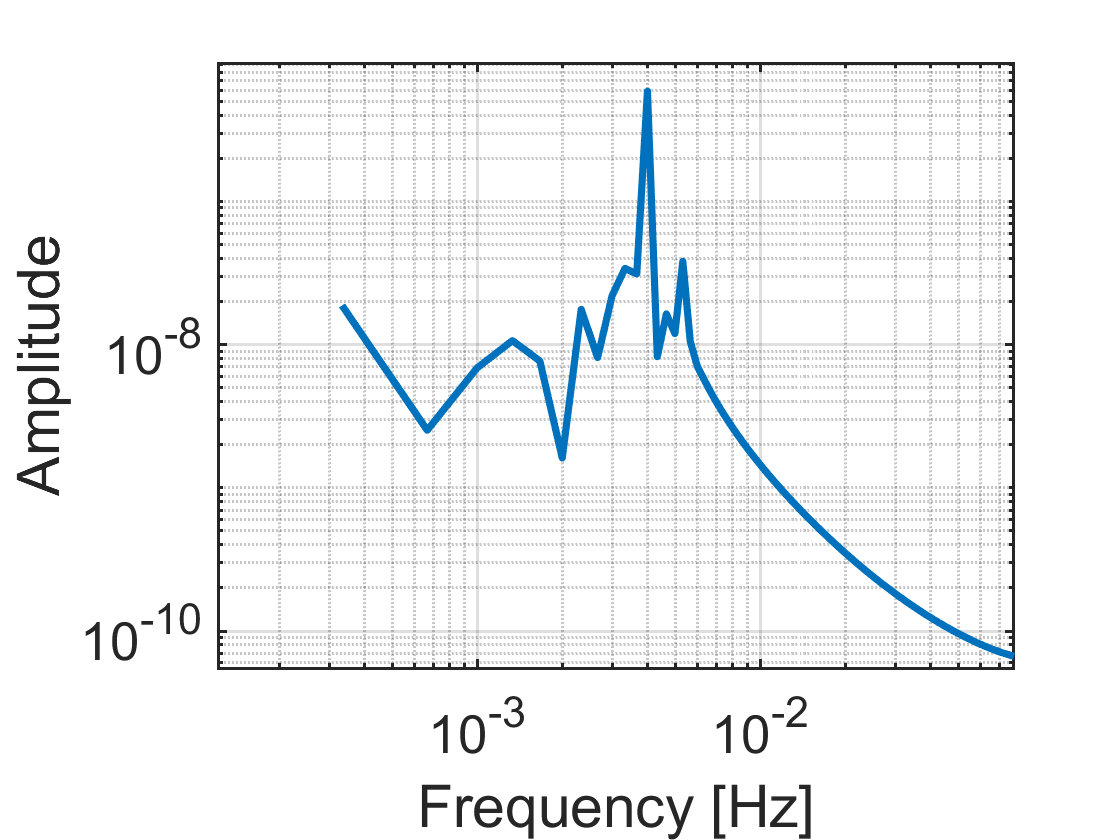

fft_plot(temp(7488: 7488+500), 0.2)

spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(8256: 8856, 4)) / 25, 0.2)

位置 1 处的索引超出数组边界(不能超出 2)。

spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(8256: 8856, 5)) / 25, 0.2)